MorphData-mush


     HeadArea     HomerFWHMArea    HomerNumber    NeckLength
    __________    _____________    ___________    __________

    3.3948e+05    38392            1.1448         531.34    



Mushroom percentage of spines per cluster


  Columns 1 through 14

   13.4984    6.3838    8.2614    0.6445   13.2041   13.3107    2.7149    5.6582    0.1928    8.2817    0.5125    5.2319   12.5647    2.4663

  Columns 15 through 16

    0.1269    4.1662



MorphData-flat


    HeadArea     HomerFWHMArea    HomerNumber
    _________    _____________    ___________

    2.859e+05    44026            1.0224     



Stubby percentage of spines per cluster


   34.0856   11.2696   15.5406    0.1592   33.5802    0.7615    0.0208    1.8760



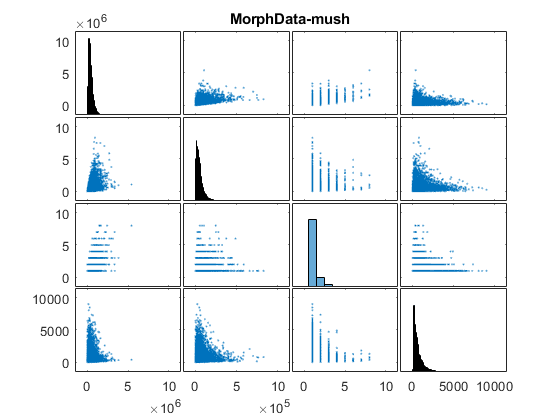

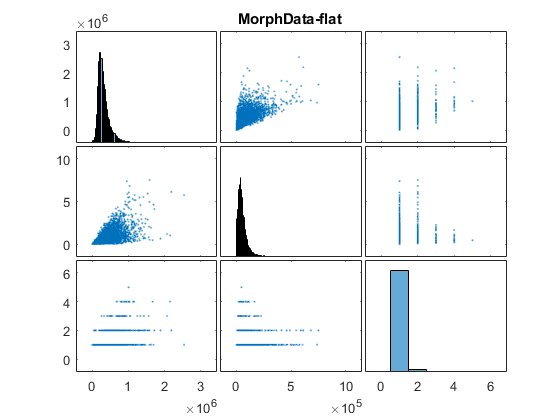

classes = {'mush', 'flat'};
cd 'Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\'
% param = {'HeadArea', 'HeadHeight', 'HeadWidth', 'HomerFWHMArea', 'HomerFWHMDioDistance', 'HomerFWHMMajorAxisLength', 'HomerFWHMMinorAxisLength', 'HomerFWHMMeanIntensity', 'HomerNumber', 'NeckLength', 'NeckArea'};
param = {'HeadArea', 'HomerFWHMArea', 'HomerNumber', 'NeckLength'};

for class = 1:numel(classes)
    %     Reading in data and cleanup
    data = load(['MorphData_' classes{class}]);
    field = fieldnames(data);
    data = data.(field{1});
    
    data = data(:, contains(data.Properties.VariableNames, param));
    
    data = standardizeMissing(data,Inf);
    if strcmp(classes{class}, 'flat')
        data.NeckLength = [];
    end
    
    figure
    plotmatrix(table2array(data));
    title(['MorphData-' classes{class}]);
    
    logdata = log10(table2array(data));
    logdata = standardizeMissing(logdata,-Inf); % to account for 0 values, which give Inf after log transform
    logdata = nanmean(logdata,1);
    logdata = 10.^logdata;
    logdata = array2table(logdata,'VariableNames',data.Properties.VariableNames);
    disp(['MorphData-' classes{class}])
    disp(logdata)
    
    % Assign each file to one of the clusters
    idx = zeros(size(data,1),1);
    head_s = data.HeadArea < logdata.HeadArea;
    head_l = data.HeadArea >= logdata.HeadArea;
    homer_s = data.HomerFWHMArea < logdata.HomerFWHMArea;
    homer_l = data.HomerFWHMArea >= logdata.HomerFWHMArea;
    homernum_s = data.HomerNumber < ceil(logdata.HomerNumber); %HomerNumber is integer. Use ceiling here to make the threshold also integer. Since I use < I want to use ceiling to have the threshold of 1.0224 turned into 2, so everything below 2 (0-1) is part of the small homernumber cluster.
    homernum_l = data.HomerNumber >= ceil(logdata.HomerNumber);
    %     For mushroom, also create the neck classifier
    if class==1
        neck_s = data.NeckLength < logdata.NeckLength;
        neck_l = data.NeckLength >= logdata.NeckLength;
    end
    
    if class==1
        idx(all([head_s,homer_s,homernum_s,neck_s],2)) = 1;
        idx(all([head_l,homer_s,homernum_s,neck_s],2)) = 2;
        idx(all([head_s,homer_l,homernum_s,neck_s],2)) = 3;
        idx(all([head_s,homer_s,homernum_l,neck_s],2)) = 4;
        idx(all([head_s,homer_s,homernum_s,neck_l],2)) = 5;
        idx(all([head_l,homer_l,homernum_s,neck_s],2)) = 6;
        idx(all([head_l,homer_s,homernum_l,neck_s],2)) = 7;
        idx(all([head_l,homer_s,homernum_s,neck_l],2)) = 8;
        idx(all([head_s,homer_l,homernum_l,neck_s],2)) = 9;
        idx(all([head_s,homer_l,homernum_s,neck_l],2)) = 10;
        idx(all([head_s,homer_s,homernum_l,neck_l],2)) = 11;
        idx(all([head_l,homer_l,homernum_l,neck_s],2)) = 12;
        idx(all([head_l,homer_l,homernum_s,neck_l],2)) = 13;
        idx(all([head_l,homer_s,homernum_l,neck_l],2)) = 14;
        idx(all([head_s,homer_l,homernum_l,neck_l],2)) = 15;
        idx(all([head_l,homer_l,homernum_l,neck_l],2)) = 16;
        disp('Mushroom percentage of spines per cluster')
        disp(sum(idx==[1:16])/size(idx,1)*100)
        csvwrite('manualclusters_mush.csv',idx)
    end
    
    if class==2
        idx(all([head_s,homer_s,homernum_s],2)) = 1;
        idx(all([head_l,homer_s,homernum_s],2)) = 2;
        idx(all([head_s,homer_l,homernum_s],2)) = 3;
        idx(all([head_s,homer_s,homernum_l],2)) = 4;
        idx(all([head_l,homer_l,homernum_s],2)) = 5;
        idx(all([head_l,homer_s,homernum_l],2)) = 6;
        idx(all([head_s,homer_l,homernum_l],2)) = 7;
        idx(all([head_l,homer_l,homernum_l],2)) = 8;
        disp('Stubby percentage of spines per cluster')
        disp(sum(idx==[1:8])/size(idx,1)*100)
        csvwrite('manualclusters_flat.csv',idx)
    end
end

idx =      6
    13
     6
    13
    13
    10
    12
     3
    10
    10


Struct contents reference from a non-struct array object.

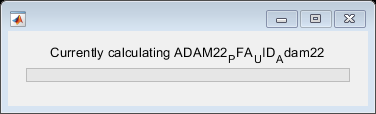

% Create cluster averages
clear idx

for class = 1:numel(classes)
    if strcmp(classes{class},'mush')
        idx = csvread('manualclusters_mush.csv')
        ProteinID=load('ProteinID_mush.mat'); ProteinID=ProteinID.ProteinID_mush;
        SpotFiles=load('SpotFiles_mush.mat'); SpotFiles=SpotFiles.SpotFiles_mush;
        
    elseif strcmp(classes{class},'flat')
        idx = csvread('manualclusters_flat.csv')
        ProteinID=load('ProteinID_flat.mat'); ProteinID=ProteinID.ProteinID_flat;
        SpotFiles=load('SpotFiles_flat.mat'); SpotFiles=SpotFiles.SpotFiles_flat;
    end
      
    proteinnames=ProteinID.Properties.VariableNames;
    w=waitbar(0,'Please wait...');
    
    for protein=1:size(proteinnames,2)
               waitbar(protein/size(proteinnames,2),w,['Currently calculating ' proteinnames{protein}]);
       
        %     Create a results folder for the protein
            if ~exist(['ClusterAverages' filesep proteinnames{protein}],'dir')
                mkdir(['ClusterAverages' filesep proteinnames{protein}]);
            end
            
            clear mess* spots cluster_id path coord* lib* dio* homer* sted*
            
            %     get the spot files and cluster memberships of spines analyzed for this protein
            spots=SpotFiles(ProteinID.(proteinnames{protein})==1);
            cluster_id=idx(ProteinID.(proteinnames{protein})==1);
            
            %% Create a library that links a spot file to its corresponding aligned images.
            
            % get the two folder names from the spot files
            path=regexp(spots,'\','split');
            path=cellfun(@(x) x(end-1),path,'UniformOutput',0);
            path=[path{:}]';
            path=unique(path);
            
            coord1=load(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep 'coordinates.mat']);
            coord1=coord1.coordinates;
            
            [~,mess_spots_rep1]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep '*_spots*.txt']);
            [~,order]=sort({mess_spots_rep1.Name});mess_spots_rep1=mess_spots_rep1(order);order=[]; %sort to avoid unordered spot files due to server bugs
            mess_spots_rep1=mess_spots_rep1(coord1.classification==1 | coord1.classification==2 | coord1.classification==3);
            [~,mess_dio_rep1]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep '*dio_aligned_150px_myfilt*.txt']);
            mess_dio_rep1=natsort({mess_dio_rep1.Name});
            [~,mess_homer_rep1]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep 'homer_aligned_150px_myfilt*.txt']);
            mess_homer_rep1=natsort({mess_homer_rep1.Name});
            [~,mess_sted_rep1]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep 'sted_aligned_150px_myfilt*.txt']);
            mess_sted_rep1=natsort({mess_sted_rep1.Name});
            lib_rep1=cat(2,{mess_spots_rep1.Name}',{mess_dio_rep1}',{mess_homer_rep1}',{mess_sted_rep1}');
            
            
            coord2=load(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep 'coordinates.mat']);
            coord2=coord2.coordinates;
            
            [~,mess_spots_rep2]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep '*_spots*.txt']);
            [~,order]=sort({mess_spots_rep2.Name});mess_spots_rep2=mess_spots_rep2(order);order=[]; %sort to avoid unordered spot files due to server bugs
            mess_spots_rep2=mess_spots_rep2(coord2.classification==1 | coord2.classification==2 | coord2.classification==3);
            [~,mess_dio_rep2]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep 'dio_aligned_150px_myfilt*.txt']);
            mess_dio_rep2=natsort({mess_dio_rep2.Name});
            [~,mess_homer_rep2]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep 'homer_aligned_150px_myfilt*.txt']);
            mess_homer_rep2=natsort({mess_homer_rep2.Name});
            [~,mess_sted_rep2]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep 'sted_aligned_150px_myfilt*.txt']);
            mess_homer_rep2=natsort({mess_homer_rep2.Name});
            lib_rep2=cat(2,{mess_spots_rep2.Name}',{mess_dio_rep2.Name}',{mess_homer_rep2.Name}',{mess_sted_rep2.Name}');
            lib=cat(1,lib_rep1,lib_rep2);
            
            
            %% Loop over the cluster IDs and find all spots that correspond to the cluster for the protein. Average them
            for i=1:max(cluster_id)
                spots_cluster=spots(cluster_id==i);
                dio=[];
                homer=[];
                sted=[];
                for j=1:numel(spots_cluster)
                    spots_avg_num=find(contains(lib(:,1),spots_cluster{j}));
                    dio(:,:,j)=dlmread(lib{spots_avg_num,2});
                    homer(:,:,j)=dlmread(lib{spots_avg_num,3});
                    sted(:,:,j)=dlmread(lib{spots_avg_num,4});
                end
                dio_avg=mean(dio,3);
                homer_avg=mean(homer,3);
                sted_avg=mean(sted,3);
                
                dlmwrite(['ClusterAverages' filesep proteinnames{protein} filesep type '_dio_cluster' num2str(i) '.txt'],dio_avg);
                dlmwrite(['ClusterAverages' filesep proteinnames{protein} filesep type '_homer_cluster' num2str(i) '.txt'],homer_avg);
                dlmwrite(['ClusterAverages' filesep proteinnames{protein} filesep type '_sted_cluster' num2str(i) '.txt'],sted_avg);
            end

    end
end